# 1

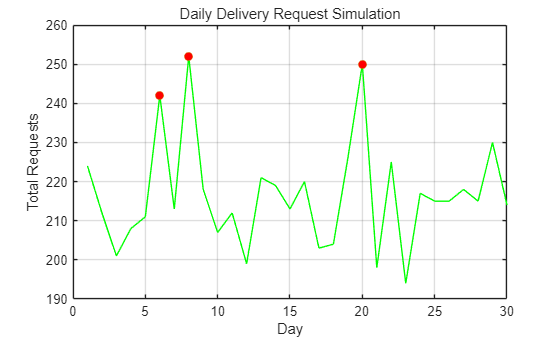

clear;clc;

%(a)
rng(14);

%(b)
request = poissrnd(18,30,12);

%(c)
dailyTotal = sum(request,2);

%(d)
busyDay = (dailyTotal>=240);

%(e)
numBusyDay = sum(busyDay);

%(f)
hourlyMean = mean(request,1);

%(g)
figure;
plot(1:30, dailyTotal, 'g');
hold on

plot(find(busyDay), dailyTotal(busyDay), 'o', 'MarkerFaceColor','r');
hold off
grid on

xlabel('Day');
ylabel('Total Requests');
title('Daily Delivery Request Simulation');

# 2

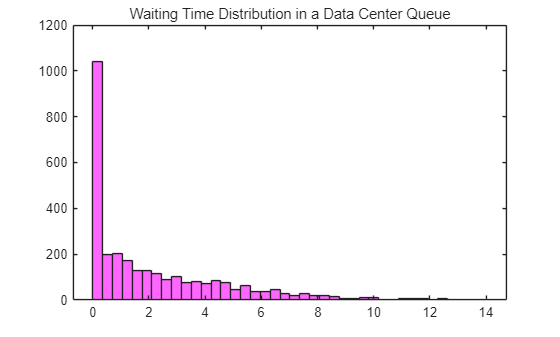

clear;clc;

%(a)
n = 3000;

%(b)
interArrival = exprnd(1.2,1,n);

%(c)
arrival = cumsum(interArrival);

%(d)
service = exprnd(0.9,1,n);

%(e)
startTime = zeros(1,n);
finishTime = zeros(1,n);

startTime(1) = arrival(1);
finishTime(1) = startTime(1) + service(1);

for i = 2:n
    startTime(i) = max(arrival(i),finishTime(i-1));
    finishTime(i) = startTime(i) + service(i);
end

%(f)
waitingTime = startTime - arrival;

%(g)
meanWait = mean(waitingTime);
maxWait = max(waitingTime);
longWaitRatio = sum(waitingTime >= 5)./n;

%(h)
figure;
histogram(waitingTime, 40, 'FaceColor','m');

%(i)
title('Waiting Time Distribution in a Data Center Queue')

# 3

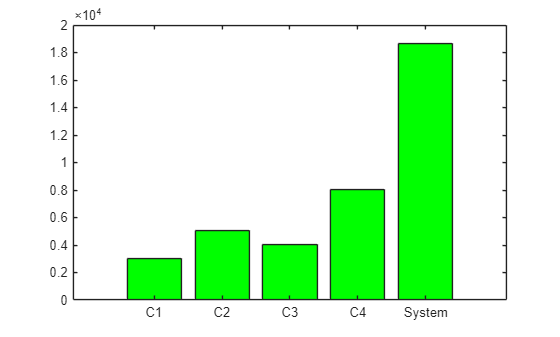

clear;clc;

%(a)
n = 100000;

%(b)
c1 = rand(1,n) < 0.97;
c2 = rand(1,n) < 0.95;
c3 = rand(1,n) < 0.96;
c4 = rand(1,n) < 0.92;

%(c)
systemWorking = c1  & c2  & c3  & c4;

%(d)
reliabilityEst = mean(systemWorking);

%(e)
reliabilityTrue = 0.97 * 0.95 * 0.96 * 0.92;

%(f)
absError = abs(reliabilityEst - reliabilityTrue);

%(g)
failCounts = [sum(~c1), sum(~c2), sum(~c3), sum(~c4), sum(~systemWorking)];

%(h)
x = 1:5;
bar(x,failCounts(x),'FaceColor','g');
xticklabels({'C1', 'C2', 'C3', 'C4', 'System'});

# 4

clear;clc;

%(a)
n = 50000

n = 50000

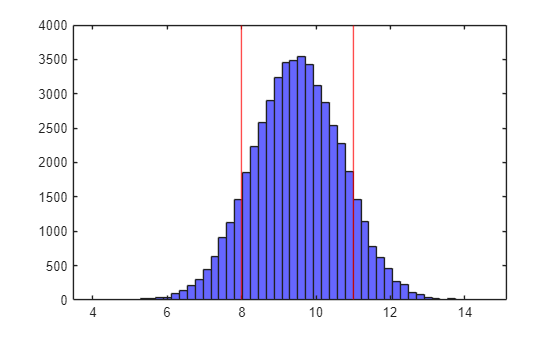

batterylife = normrnd(9.5,1.2,1,n);

%(b)
lowBattery = batterylife < 8;

%(c)
normalBattery = batterylife < 11 & batterylife >= 8;

%(d)
excellentBattery = batterylife >= 11;

%(e)
gradeCounts = sum([lowBattery; normalBattery; excellentBattery]');

%(f)
gradeRatio = gradeCounts/n;

%(g)
figure;
histogram(batterylife,50,'FaceColor','b');
hold on
xline([8,11],'r')

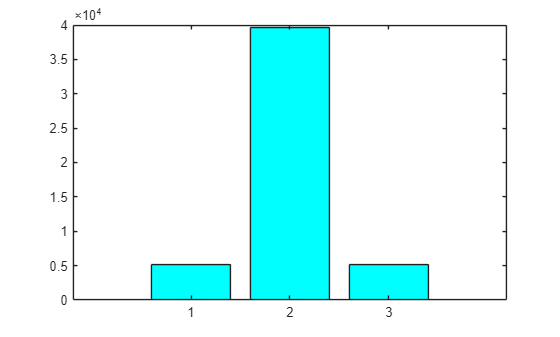


%(h)
figure;
bar(gradeCounts,'facecolor','c');

# 5

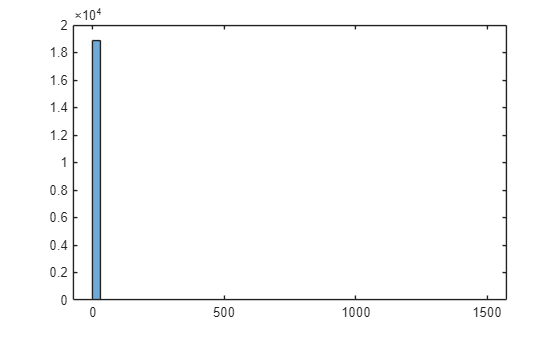

clear;clc;

%(a)
n = 20000;

%(b)
hasClaim = rand(1,n) < 0.06;

%(c)
claimAmount = normrnd(800, 250, 1, n);

%(d)
claimAmount(claimAmount < 0) = 0;

%(e)
claimPayment = hasClaim .* claimAmount;

%(f)
totalPayment = sum(claimPayment);
meanPayment = totalPayment./n;
meanClaimOnly = totalPayment./sum(hasClaim);

%(g)
numLargeClaim = sum(claimPayment >= 1200);

%(h)
figure;
histogram(claimPayment);

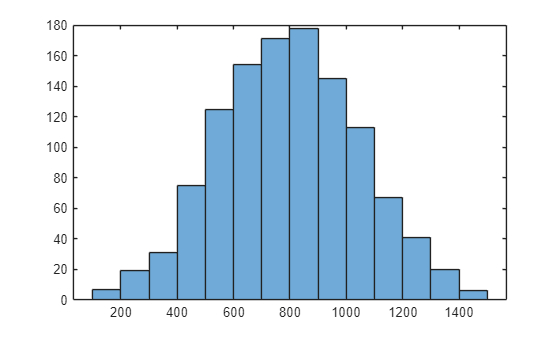

figure;
histogram(claimPayment(claimPayment > 0));

# 6

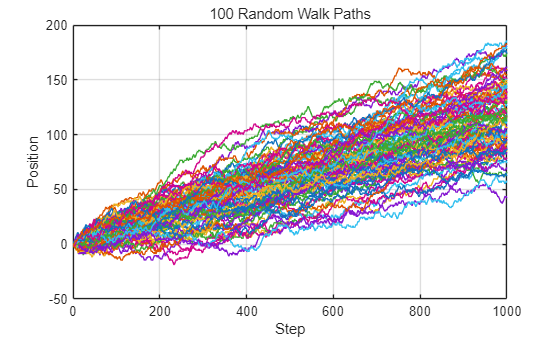

clear; clc;

%(a)
n = 1000;   % 단계 수
m = 100;    % 경로 수

%(b)
steps = 2 * (rand(n,m) < 0.56) - 1;
% rand(n,m) < 0.56 이면 true = 1
% 2*1 - 1 = +1  오른쪽 이동
% 2*0 - 1 = -1  왼쪽 이동

%(c)
walks = cumsum(steps);

%(d)
figure;
plot(1:n, walks);
xlabel('Step');
ylabel('Position');
title('100 Random Walk Paths');
grid on;

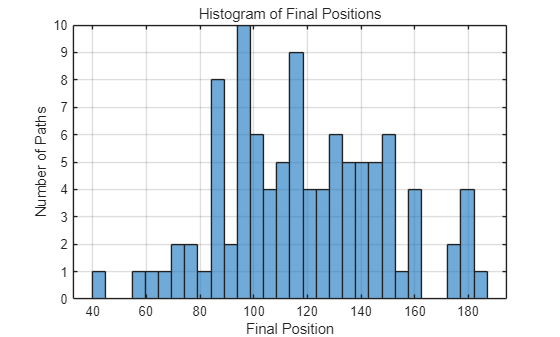


%(e)
finalPosition = walks(end, :);

%(f)
meanFinal = mean(finalPosition);
stdFinal = std(finalPosition);

%(g)
rightDriftRatio = sum(finalPosition >= 100) / m;

%(h)
figure;
histogram(finalPosition, 30);
xlabel('Final Position');
ylabel('Number of Paths');
title('Histogram of Final Positions');
grid on;

# 7

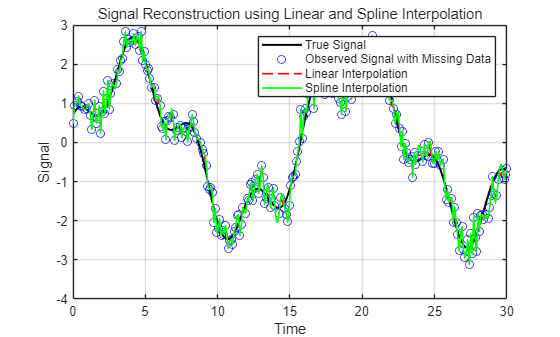

clear; clc;

%(a)
rng(7);

%(b)
t = linspace(0, 30, 300);

%(c)
trueSignal = 2*sin(0.4*t) + 0.7*cos(1.5*t);

%(d)
obsSignal = trueSignal + 0.25*randn(size(t));

%(e)
missingIdx = randperm(length(t), 45);
obsSignal(missingIdx) = NaN;

%(f)
valid = ~isnan(obsSignal);

%(g)
recLinear = interp1(t(valid), obsSignal(valid), t, 'linear');

%(h)
recSpline = interp1(t(valid), obsSignal(valid), t, 'spline');

%(i)
rmseLinear = sqrt(mean((trueSignal - recLinear).^2));
rmseSpline = sqrt(mean((trueSignal - recSpline).^2));

%(j)
figure;
plot(t, trueSignal, 'k', 'LineWidth', 1.5);
hold on;
plot(t, obsSignal, 'bo');
plot(t, recLinear, 'r--', 'LineWidth', 1.2);
plot(t, recSpline, 'g-', 'LineWidth', 1.2);

xlabel('Time');
ylabel('Signal');
title('Signal Reconstruction using Linear and Spline Interpolation');
legend('True Signal', 'Observed Signal with Missing Data', ...
       'Linear Interpolation', 'Spline Interpolation');

grid on;

# 8

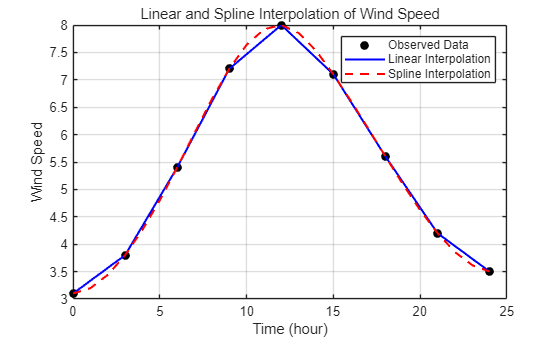

clear; clc;

%(a)
timeObs = [0 3 6 9 12 15 18 21 24];
windObs = [3.1 3.8 5.4 7.2 8.0 7.1 5.6 4.2 3.5];

%(b)
timeHourly = 0:1:24;

%(c)
windLinear = interp1(timeObs, windObs, timeHourly, 'linear');

%(d)
windSpline = interp1(timeObs, windObs, timeHourly, 'spline');

%(e)
diffWind = windSpline - windLinear;

%(f)
maxDiff = max(abs(diffWind));

%(g)
figure;
plot(timeObs, windObs, 'ko', 'MarkerFaceColor', 'k');
hold on;
plot(timeHourly, windLinear, 'b-', 'LineWidth', 1.5);
plot(timeHourly, windSpline, 'r--', 'LineWidth', 1.5);

xlabel('Time (hour)');
ylabel('Wind Speed');
title('Linear and Spline Interpolation of Wind Speed');
legend('Observed Data', 'Linear Interpolation', 'Spline Interpolation');
grid on;


%(h)
figure;
plot(timeHourly, diffWind, 'm-o', 'LineWidth', 1.5);

xlabel('Time (hour)');
ylabel('Spline - Linear');
title('Difference between Spline and Linear Interpolation');
grid on;

# 9

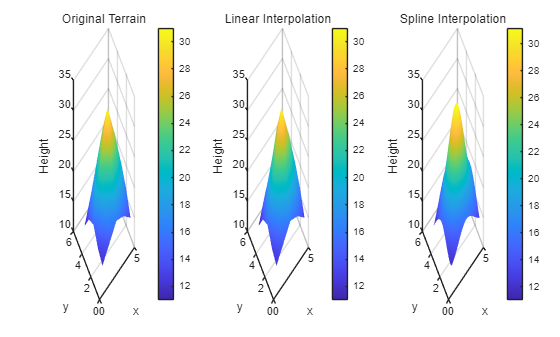

clear; clc; close all;

%(a) 원래 격자 생성
[X, Y] = meshgrid(1:5, 1:5);

%(b) 높이 행렬 H 생성
H = [12 14 16 15 13;
     13 18 22 20 16;
     15 23 31 25 18;
     14 20 26 24 17;
     11 15 18 16 14];

%(c) 촘촘한 격자 생성
[Xq, Yq] = meshgrid(1:0.1:5, 1:0.1:5);

%(d) 선형 보간
HqLinear = interp2(X, Y, H, Xq, Yq, 'linear');

%(e) 스플라인 보간
HqSpline = interp2(X, Y, H, Xq, Yq, 'spline');

%(f), (g) tiledlayout으로 비교
figure;
tiledlayout(1, 3);

% 원래 지형
nexttile;
surf(X, Y, H);
shading interp;
colorbar;
xlabel('x');
ylabel('y');
zlabel('Height');
title('Original Terrain');
grid on;

% 선형 보간 지형
nexttile;
surf(Xq, Yq, HqLinear);
shading interp;
colorbar;
xlabel('x');
ylabel('y');
zlabel('Height');
title('Linear Interpolation');
grid on;

% 스플라인 보간 지형
nexttile;
surf(Xq, Yq, HqSpline);
shading interp;
colorbar;
xlabel('x');
ylabel('y');
zlabel('Height');
title('Spline Interpolation');
grid on;

# 10

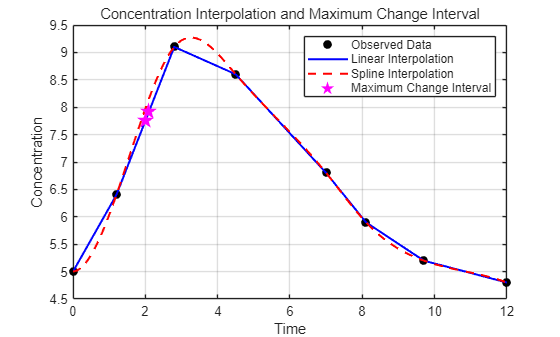

clear; clc; close all;

%(a)
tObs = [0 1.2 2.8 4.5 7.0 8.1 9.7 12.0];
cObs = [5.0 6.4 9.1 8.6 6.8 5.9 5.2 4.8];

%(b)
tq = 0:0.1:12;

%(c)
cqLinear = interp1(tObs, cObs, tq, 'linear');

%(d)
cqSpline = interp1(tObs, cObs, tq, 'spline');

%(e)
deltaC = diff(cqLinear);

%(f)
[~, idxMaxChange] = max(abs(deltaC));

%(g)
changeInterval = [tq(idxMaxChange), tq(idxMaxChange+1)];

%(h)
figure;
plot(tObs, cObs, 'ko', 'MarkerFaceColor', 'k');
hold on;
plot(tq, cqLinear, 'b-', 'LineWidth', 1.5);
plot(tq, cqSpline, 'r--', 'LineWidth', 1.5);

% 변화가 가장 큰 구간의 두 끝점 표시
plot(changeInterval, cqLinear(idxMaxChange:idxMaxChange+1), ...
     'mp', 'MarkerSize', 12, 'MarkerFaceColor', 'm');

xlabel('Time');
ylabel('Concentration');
title('Concentration Interpolation and Maximum Change Interval');
legend('Observed Data', 'Linear Interpolation', 'Spline Interpolation', ...
       'Maximum Change Interval');
grid on;


% 결과 출력
disp('가장 변화가 큰 시간 구간:');

가장 변화가 큰 시간 구간:


disp(changeInterval);

    2.0000    2.1000




disp('해당 구간의 농도 변화량:');

해당 구간의 농도 변화량:


disp(deltaC(idxMaxChange));

    0.1688



# 11

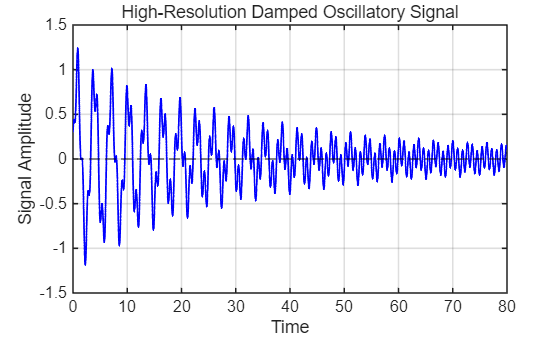

clear; clc; close all;

%(a)
t = linspace(0, 80, 12000);

%(b)
y = exp(-0.04*t).*sin(2*t) + 0.3*exp(-0.01*t).*cos(7*t);

%(c)
figure('Color', 'w');

%(d)
plot(t, y, 'b-', 'LineWidth', 1.3);
hold on;

%(e)
yline(0, 'k--', 'LineWidth', 1.0);

%(f)
xlabel('Time');
ylabel('Signal Amplitude');
title('High-Resolution Damped Oscillatory Signal');

%(g)
xlim([0 80]);
grid on;
box on;

%(h)
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1.2;

%(i)
print(gcf, 'damped_signal.png', '-dpng', '-r300');

# 12

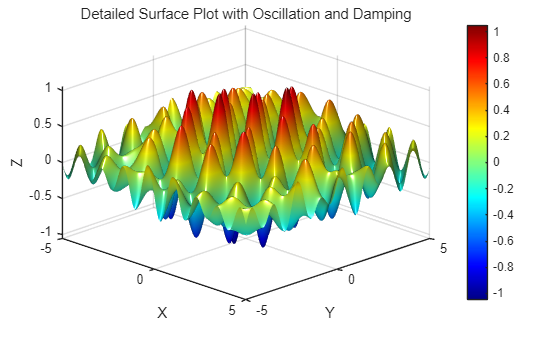

clear; clc; close all;

%(a)
x = linspace(-5, 5, 600);
y = linspace(-5, 5, 600);

%(b)
[X, Y] = meshgrid(x, y);

%(c)
Z = exp(-0.06*(X.^2 + Y.^2)) .* sin(4*X) .* cos(3*Y) ...
    + 0.2*sin(X.*Y);

%(d)
figure;
surf(X, Y, Z);

%(e)
shading interp;
colormap(jet);
colorbar;

%(f)
xlabel('X');
ylabel('Y');
zlabel('Z');

%(g)
title('Detailed Surface Plot with Oscillation and Damping');

%(h)
view(45, 30);
camlight headlight;
lighting phong;


%(i)
maxZ = max(Z(:));
minZ = min(Z(:));

%(j)
idxMax = find(Z == maxZ, 1);
idxMin = find(Z == minZ, 1);

[rowMax, colMax] = ind2sub(size(Z), idxMax);
[rowMin, colMin] = ind2sub(size(Z), idxMin);

maxPoint = [X(rowMax, colMax), Y(rowMax, colMax), Z(rowMax, colMax)];
minPoint = [X(rowMin, colMin), Y(rowMin, colMin), Z(rowMin, colMin)];

disp('Maximum Point [x y z]:');

Maximum Point [x y z]:


disp(maxPoint);

    1.1770    1.0434    1.0504




disp('Minimum Point [x y z]:');

Minimum Point [x y z]:


disp(minPoint);

   -1.1770    1.0434   -1.0504



# 13

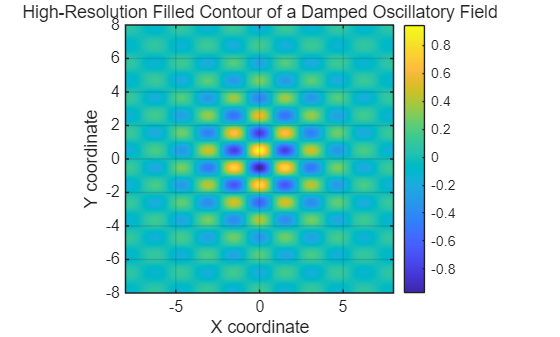

clear; clc; close all;

%(a)
x = linspace(-8, 8, 800);
y = linspace(-8, 8, 800);

%(b)
[X, Y] = meshgrid(x, y);

%(c)
Z = cos(2*X) .* sin(3*Y) ./ (1 + 0.1*(X.^2 + Y.^2));

%(d)
figure;
contourf(X, Y, Z, 70, 'LineColor', 'none');

%(e)
colormap(parula);
colorbar;
axis equal;
grid on;
box on;

%(f)
xlabel('X coordinate');
ylabel('Y coordinate');

%(g)
title('High-Resolution Filled Contour of a Damped Oscillatory Field');

%(h)
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1.2;

# 14

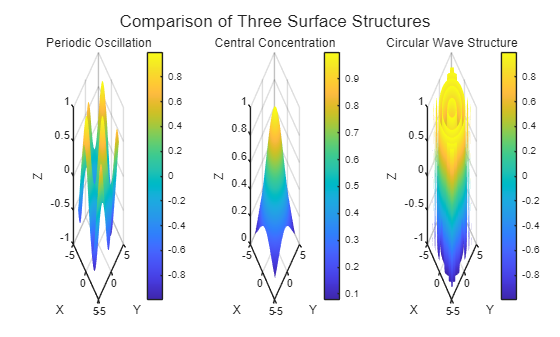

clear; clc; close all;

%(a)
x = linspace(-4, 4, 300);
y = linspace(-4, 4, 300);

%(b)
[X, Y] = meshgrid(x, y);

%(c)
Z1 = sin(X) .* cos(Y);
Z2 = exp(-0.08 * (X.^2 + Y.^2));
Z3 = sin(X.^2 + Y.^2);

%(d)
figure;
tiledlayout(1, 3);

%(e), (f), (g)
nexttile;
surf(X, Y, Z1);
shading interp;
colorbar;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Periodic Oscillation');
view(45, 30);

nexttile;
surf(X, Y, Z2);
shading interp;
colorbar;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Central Concentration');
view(45, 30);

nexttile;
surf(X, Y, Z3);
shading interp;
colorbar;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Circular Wave Structure');
view(45, 30);

%(h)
sgtitle('Comparison of Three Surface Structures');

# 15

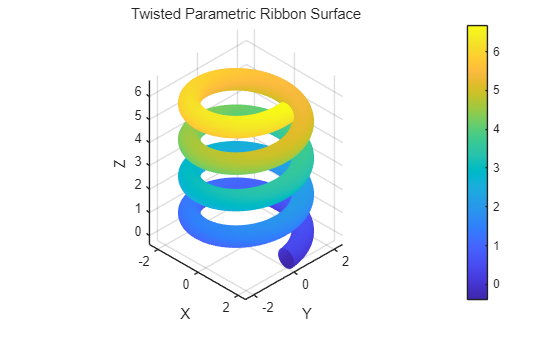

clear; clc; close all;

%(a)
u = linspace(0, 8*pi, 500);
v = linspace(-pi, pi, 180);

%(b)
[U, V] = meshgrid(u, v);

%(c)
X = (2 + 0.4*cos(V)) .* cos(U);
Y = (2 + 0.4*cos(V)) .* sin(U);
Z = 0.25*U + 0.4*sin(V);

%(d)
figure('Color', 'w');
surf(X, Y, Z);

%(e)
shading interp;
colormap(parula);
colorbar;

%(f)
xlabel('X');
ylabel('Y');
zlabel('Z');

%(g)
title('Twisted Parametric Ribbon Surface');

%(h)
axis equal;
axis tight;
grid on;
view(45, 35);

%(i)
print(gcf, 'twisted_ribbon.png', '-dpng', '-r300');

# 16

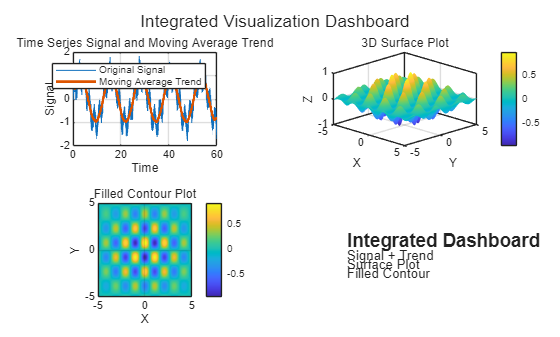

clear; clc; close all;

%(a)
rng(3);

%(b)
t = linspace(0, 60, 6000);
signal = sin(0.5*t) + 0.4*sin(3*t) + 0.15*randn(size(t));

%(c)
trend = movmean(signal, 200);

%(d)
x = linspace(-5, 5, 300);
y = linspace(-5, 5, 300);
[X, Y] = meshgrid(x, y);

%(e)
Z = exp(-0.05*(X.^2 + Y.^2)) .* cos(3*X) .* sin(2*Y);

%(f)
figure('Color', 'w');
tiledlayout(2, 2);

%(g) 첫 번째 tile: 2차원 시계열 그래프
nexttile;
plot(t, signal, 'LineWidth', 0.8);
hold on;
plot(t, trend, 'LineWidth', 2.0);
xlabel('Time');
ylabel('Signal');
title('Time Series Signal and Moving Average Trend');
legend('Original Signal', 'Moving Average Trend');
grid on;
box on;

%(h) 두 번째 tile: 3차원 surface 그래프
nexttile;
surf(X, Y, Z);
shading interp;
colorbar;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D Surface Plot');
view(45, 30);
grid on;
box on;

%(i) 세 번째 tile: filled contour 그래프
nexttile;
contourf(X, Y, Z, 50, 'LineColor', 'none');
colorbar;
xlabel('X');
ylabel('Y');
title('Filled Contour Plot');
axis equal;
grid on;
box on;

%(j) 네 번째 tile은 비워두거나 설명용으로 사용
nexttile;
axis off;
text(0.1, 0.6, 'Integrated Dashboard', 'FontSize', 14, 'FontWeight', 'bold');
text(0.1, 0.45, 'Signal + Trend');
text(0.1, 0.35, 'Surface Plot');
text(0.1, 0.25, 'Filled Contour');

%(k)
sgtitle('Integrated Visualization Dashboard');

%(l) 저장이 필요한 경우
print(gcf, 'visualization_dashboard.png', '-dpng', '-r300');